I = imread("car2.jpg");
I = rgb2gray(I);
I = imresize(I, [256 256]);
sift = detectSIFTFeatures(I);
imshow(I);
hold on;
plot(sift.selectStrongest(3))
num = sift.selectStrongest(1)

num =   SIFTPoints with properties:

          Scale: 3.4358
    Orientation: 0
         Octave: 0
          Layer: 3
       Location: [206.2893 15.1828]
         Metric: 0.0942
          Count: 1


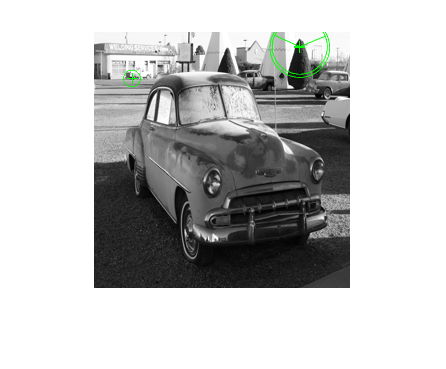

[features, valid_points] = extractFeatures(I, num);
plot(valid_points,'showOrientation',true);

num

num =   SIFTPoints with properties:

          Scale: 3.4358
    Orientation: 0
         Octave: 0
          Layer: 3
       Location: [206.2893 15.1828]
         Metric: 0.0942
          Count: 1


valid_points

valid_points =   2×1 SIFTPoints array with properties:

          Scale: [2×1 single]
    Orientation: [2×1 single]
         Octave: [2×1 int32]
          Layer: [2×1 int32]
       Location: [2×2 single]
         Metric: [2×1 single]
          Count: 2


sift

sift =   402×1 SIFTPoints array with properties:

          Scale: [402×1 single]
    Orientation: [402×1 single]
         Octave: [402×1 int32]
          Layer: [402×1 int32]
       Location: [402×2 single]
         Metric: [402×1 single]
          Count: 402
